# 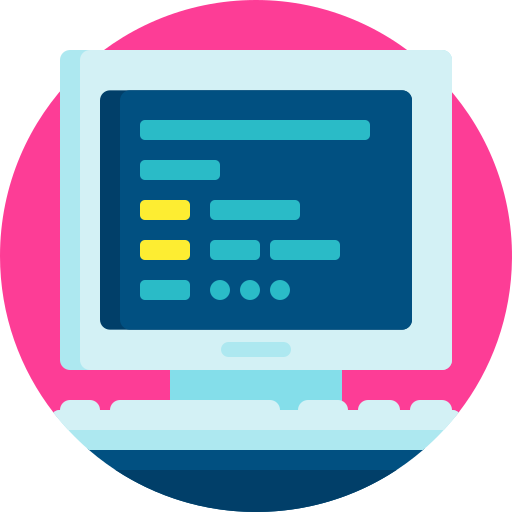

# Virtual Lab 2 - Representing orientation

#### This Virtual Lab covers Chapter 3 of the course notes

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive/USB. 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (or CMD+ENTER).

## Representing orientation

So far, we have been handling our orientation indirectly, using encoded forms, such as the rotation matrix. If required, we can extract the actual orientation descriptor, which we may require for data analysis, filtering, or feedback control (more on this later).

### Euler angles

A popular choice to describe orientation is to use Euler angles. In the case of intrinsic *ZYX* Euler angles (see Section 3.2), we can describe the orientation of one frame with respect to another using 

$\eta = \pmatrix{\phi \cr\theta   \cr \psi}$,

where $\phi$, $\theta$, and $\psi$ are referred to as the roll, pitch, and yaw angles, respectively. Notably, these three angles have the following bounds:

- $\{\phi,\psi\}\in[-\pi,\pi]$, 

- $\theta\in[-\frac{\pi}{2},\frac{\pi}{2}]$.

If we know what our Euler angles are, we can construct our ZYX rotation matrix using three sequential rotations about three newly formed axes, which yields

${^W{\bf R}_B}={^W{\bf R}_Z}{^Z{\bf R}_Y}{^Y{\bf R}_B}$.

The "*ZYX" *label above indicates that we sequentially rotate about $\hat{\bf z}_W$, $\hat{\bf y}_Z$, and $\hat{\bf x}_Y$, where frame${\{Z\}$describes the orientation after rotating about $\hat{\bf z}_W$, and frame ${\{Y\}$ describes the orientation after rotating about $\hat{\bf y}_Z$. Specifically, we will be systematically moving through four reference frames: ${\{W\} \rightarrow {\{Z\} \rightarrow {\{Y\} \rightarrow {\{X\} ={\{B\} $, which is illustrated in the figure below.

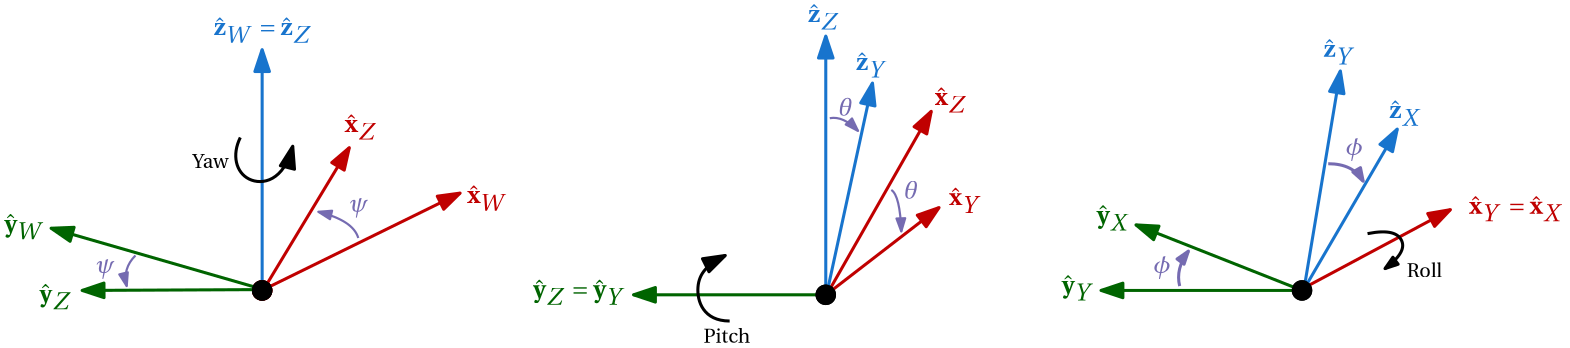

We can visualise the rotations using the code below, using a fixed-wing UAV as our robot of interest.

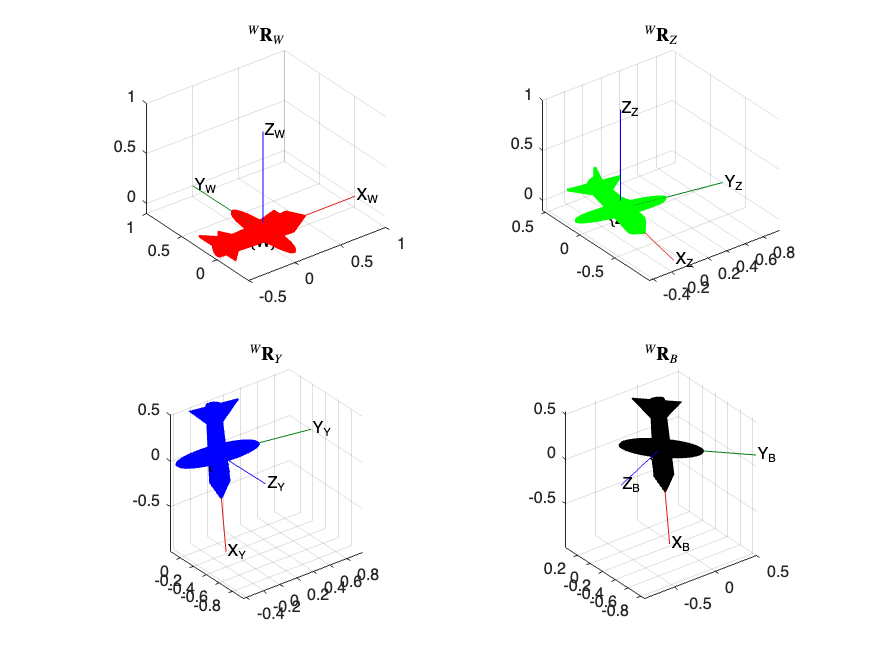

phi = 50*pi/180;
the = 80*pi/180;
psi = -100*pi/180;

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],rotm2quat(eye(3)),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],rotm2quat(Rz),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf R}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],rotm2quat(Rz*Ry),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf R}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],rotm2quat(Rz*Ry*Rx),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf R}_B$',Interpreter='latex'),grid on

Note (based on how we have used `plotTransforms` above) that we chained together the rotation matrices as needed when deriving the new frame orientation. The matrix multiplication order is also very important and is required to follow the convention stated for the particular Euler angle vector. 

**  Question 1: **Under what generalised condition will ${^W{\bf R}_B}={^Y{\bf R}_B}$?

We can also recover the Euler angles from a rotation matrix, if need be, using the equations below


$$\begin{array}{cc}\phi = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$
     
$$\begin{array}{cc}\theta = -\arcsin{r_{31},\end{array}$$
     
$$\begin{array}{cc}\psi = \arctan(\frac{r_{21}}{r_{11}}),\end{array}$$


where


$$\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


**  Question 2: **Given a rotation matrix of $\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    -0.0302 & 0.502 & -0.864 \\    -0.171 & -0.855 & -0.490 \\    -0.985 & 0.1335 & 0.112    \\ \end{array}\right]   \end{array}$, determine the corresponding roll-pitch-yaw angles in degrees.

%Code block (if required)
R = Rz*Ry*Rx;
R_ = [-.0302 0.502 -0.864; -0.171 -0.855 -0.490; -0.985 0.1335 0.112];

phi_ = atan2( R_(3,2),R_(3,3) )*180/pi

phi_ =   50.004987270512885


theta_ = -asin( R_(3,1) )*180/pi

theta_ =   80.063632927859274


psi_ = atan2( R_(2,1),R_(1,1) )*180/pi

psi_ =     -1.000156253551073e+02


### Gimbal lock

One of the main problems with using Euler angles is when two rotation axes used in defining the rotation order become aligned (parallel or anti-parallel), thereby resulting in the loss of one rotational degree of freedom. This is known as *gimbal lock *and occurs when the first and third rotation take place about the same inertial-frame axis.

**  Question 3: **What value(s) of $\theta$ result in gimbal lock when using *ZYX* intrinsic Euler angles?

We can test out the gimbal lock phenomenon by specifying twp different sets of ZYX Euler angles while in gimbal lock and showing that they result in the same orientation. Note that if the first and third axes become parallel, the roll and yaw angles some, whereas when the first and third axes are anti-parallel, the roll and yaw are differenced, based on right-hand rule.

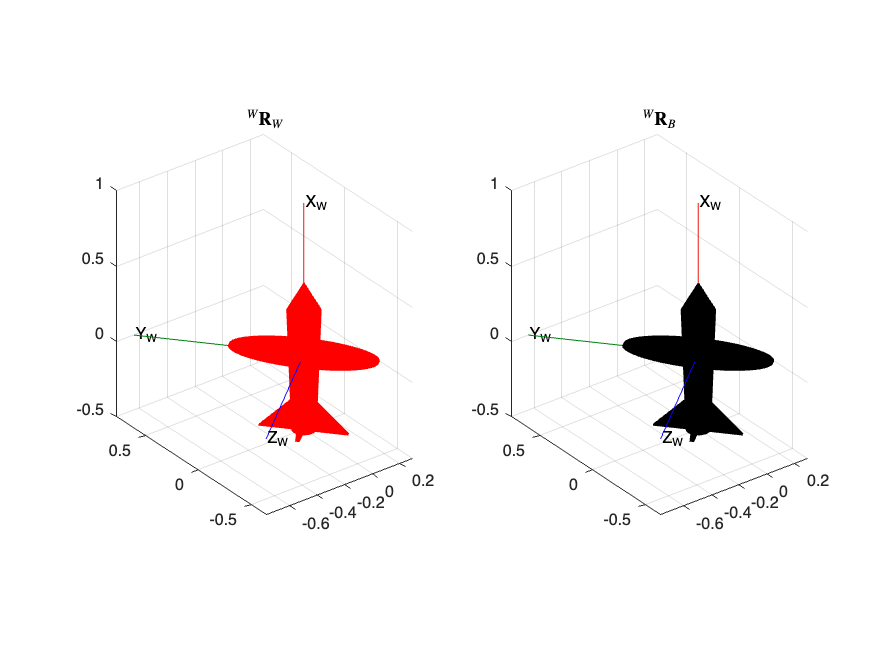

phi1 = 20*pi/180;   phi2 = 0*pi/180; 
the1 = -90*pi/180;    the2 = -90*pi/180;
psi1 = 20*pi/180;   psi2 = 40*pi/180;

Rz1 = [cos(psi1) -sin(psi1) 0; %principle rotation about z-axis
      sin(psi1) cos(psi1) 0;
      0          0       1];
Ry1 = [cos(the1)   0   sin(the1);  %principle rotation about y-axis
      0          1       0;
     -sin(the1)   0   cos(the1)];
Rx1 = [1     0        0;     %principle rotation about x-axis
      0 cos(phi1) -sin(phi1);
      0 sin(phi1) cos(phi1)];

Rz2 = [cos(psi2) -sin(psi2) 0; %principle rotation about z-axis
      sin(psi2) cos(psi2) 0;
      0          0       1];
Ry2 = [cos(the2)   0   sin(the2);  %principle rotation about y-axis
      0          1       0;
     -sin(the2)   0   cos(the2)];
Rx2 = [1     0        0;     %principle rotation about x-axis
      0 cos(phi2) -sin(phi2);
      0 sin(phi2) cos(phi2)];

figure,hold on
subplot(1,2,1),plotTransforms([0 0 0],rotm2quat(Rz1*Ry1*Rx1),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W$',Interpreter='latex'),grid on
subplot(1,2,2),plotTransforms([0 0 0],rotm2quat(Rz2*Ry2*Rx2),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_B$',Interpreter='latex'),grid on

**  Question 4: **What value(s) of $\theta$ result in gimbal lock when using *ZYZ* intrinsic Euler angles?

### Quaternions

The quaternion is a popular choice of encoding attitude that completely avoids the issue of gimbal lock by rather describing the orientation as a single rotation about some defined axis that intercepts the relevant reference frame origin. The (unit) quaternion is defined as

${^W{\bf q}_B}= \left[\matrix{q_o & q_x & q_y & q_z}\right]^T =  \left[\matrix{ \cos(\theta/2) \cr \sin( \theta/2 ) {^W\hat{\bf v}} } \right]$,

where $\theta$ describes the rotation angle, and $\hat{\bf v}$ is the unit-length vector that the rotation takes place about. Note that the quaternion (and rotation vector) also uses the subscript-superscript notation to indicate relative orientation. This is important because the quaternion functions in a similar way to the rotation matrix — where rotations take place relative to a defined reference frame.

We can visualise the application of the quaternion on our fixed-wing UAV using the code below.

v_x = 0;
v_y = 1;
v_z = 0;
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalise v so that it always has unit length.

theta = 10*pi/180;
q = [cos(theta/2); sin(theta/2)*v];

figure
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal,title('Body-frame shown with respect to inertial-frame'),grid on

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','--','Marker','x','LineWidth',2)
axis equal,title('Before rotation'),grid on
subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","black")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','--','Marker','x','LineWidth',2)
axis equal,title('After rotation'),grid on

Play around with different axis and angle combinations, starting with principal axis rotations (e.g. $\hat{\bf v}=[1~0~0]^T$) .	 

Using a specified rotation axis and angle, any orientation can be defined, and we never need to worry about gimbal lock! There is one catch though, the orientation is not uniquely defined by a quaternion. Instead, each orientation can be described by two different quaternions — (i) a rotation about some vector, $\hat{\bf v}$, with an angle of $\gamma$, and (ii) a rotation about vector $-\hat{\bf v}$ with an angle of $-\gamma$. 

%example (using info from previous code block)
theta1 = theta; 
v1 = v;
q1 = [cos(theta1/2); sin(theta1/2)*v1];

theta2 = -theta1;
v2 = -v1;
q2 = [cos(theta2/2); sin(theta2/2)*v2];

[q1 q2] %quaternions will always be the same.


Geometrically, the rotations are equivalent, but this may cause issues if we are using a series of sequential incremental quaternion rotations to define a trajectory (fortunately/unfortunately this wont be covered in the MEC4127F syllabus!).

Recovering the rotation angle and vector from a quaternion is done by

$\theta = 2 \cos^{-1} (q_o)$,

${^W\hat{\bf v}}=\frac{1}{\sin(\theta/2)} \left[ \matrix{ q_x & q_y & q_z} \right]^T$,

for example:

the = 2*acos( q(1) );
the_deg = the*180/pi
v = 1/sin( the/2 )*q(2:4)

Note that the above equation will always return a positive $\theta$ value. The rotational direction will be embedded in the recovered $^W\hat{\bf v}$ value.

### Relationship between Euler angles and quaternions

Just as we could fully define a rotation (matrix) using three sequential rotations, parameterised by the three Euler angles, we can achieve the same result using quaternions. The only difference is that quaternions make use of a special multiplication, known as the Hamilton product, e.g.

${^A{\bf q}_C}={^A{\bf q}_B} \otimes {^B{\bf q}_C}$.

While we will not focus on the explicit quaternion multiplication in this course, we can use MATLAB's [`quatmultiply`](https://www.mathworks.com/help/aerotbx/ug/quatmultiply.html) to multiply two quaternions.

%example
q_c2b = [1/sqrt(2) 0 1/sqrt(2) 0];
q_b2a = [0 0 0 1];
q_c2a = quatmultiply(q_b2a,q_c2b) 

You think of a quaternion in a similar way to a rotation matrix — it is encoding orientation, but in a more compact form (a $4\times1$ vector instead of a $3\times 3$ matrix). Remembering that a quaternion is defined by a rotation vector and angle, we can define a quaternion that corresponds to our principle $z$-axis rotation

psi = 20*pi/180;
Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];

v = [0 0 1];
qz = [cos(psi/2) sin(psi/2)*v ] %quaternion corresponding to principle rotation about z-axis

`Rz and qz `should describe the same orientation, and we can check this using

qz_ = rotm2quat(Rz) %qz_ should be equivalent to qz

The full 3D description of our orientation can also be described by a quaternion, but parameterised by Euler angles, using

${^W{\bf q}_B}={^W{\bf q}_Z} \otimes {^Z{\bf q}_Y} \otimes {^Y{\bf q}_B}$,

where each quaternion on the right-side of the equation above corresponds to a principle axis rotation.

**  Question 12: **Define ${^W{\bf q}_Z}$, ${^Z{\bf q}_Y}$, and ${^Y{\bf q}_B}$ in code using the Euler angles from before and hence find ${^W{\bf q}_B}$ using [`quatmultiply`](https://www.mathworks.com/help/aerotbx/ug/quatmultiply.html)`. `Paste your code in the answer block.

*Hint: *`quatmultiply`* only takes in two arguments, but you can chain multiple together.*

%Q12
phi = -40*pi/180;
the = -80*pi/180;
psi = 20*pi/180;

q_z2w = [cos(psi/2) sin(psi/2)*[0 0 1] ];
q_y2z = [cos(the/2) sin(the/2)*[0 1 0] ];
q_b2y = [cos(phi/2) sin(phi/2)*[1 0 0] ];

q_b2w = quatmultiply( quatmultiply(q_z2w,q_y2z), q_b2y)
% q_b2w = kron( kron(q_z2w,q_y2z), q_b2y)

function plotReferenceFramesAndVectors(R_b2w,t_b2w,a_b)

a_w = R_b2w*a_b+t_b2w;

figure,hold on
plotTransforms(t_b2w',rotm2quat(R_b2w))
vec = line([t_b2w(1) a_w(1)],[t_b2w(2) a_w(2)],[t_b2w(3) a_w(3)]);
vec.Color = 'magenta';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
text(t_b2w(1),t_b2w(2),'   $\{B\}$','Interpreter','latex');

plotTransforms([0 0 0],[1 0 0 0])
vec = line([0 a_w(1)],[0 a_w(2)],[0 a_w(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on
text(0,0,'   $\{W\}$','Interpreter','latex');
end